$F_c$ - driving force - $[N]$

$\eta_g$ - gearbox efficiency - $[-]$

$K_g$ - gear ratio - $[-]$

$r_{mp}$ - motor pinion radius (prumer pastorku) - $[m]$


$$F_c = \frac{\eta_g K_g \tau_M}{r_{mp}
}$$


$M_c$- mass of the cart - $[kg]$

$x_C$ - cart position - $[m]$

$B_{eq}$ - equivalent viscous damping coefficient - $[\frac{N m\; s}{rad}]$ 

eta_g = 0.9 %gearbox efficiency

eta_g = 0.9000

K_g = 3.71 %gearbox gear ratio

K_g = 3.7100

k_t = 7.68e-3 %motor current-torque constant

k_t = 0.0077

k_m = 7.68e-3 %motor back-emf constant

k_m = 0.0077

R_m = 2.6 %motor armature resistance

R_m = 2.6000

r_mp = 6.35e-3 %motor pinion radius (prumer pastorku)

r_mp = 0.0064

eta_m = 0.69 %motor efficiency

eta_m = 0.6900

A_m = eta_g * K_g * eta_m * k_t / r_mp / R_m %actuator gain

A_m = 1.0717

J_p = 1.2e-3 %moment of inertia about CoM, medium length pendulum

J_p = 0.0012

L_p = 0.3365 %full length of the pendulum

L_p = 0.3365

l_p = L_p/2

l_p = 0.1683

M_p = 0.127 %pendulum mass

M_p = 0.1270

%J_p = J_pCoM + M_p * l_p^2
M_c = 0.38 %cart mass

M_c = 0.3800

J_m = 3.9e-7 %motor moment of inertia

J_m = 3.9000e-07

J_eq = M_c + eta_g*K_g^2*J_m/r_mp^2

J_eq = 0.4998

B_eq = 4.3 %equivalent viscous damping coefficient (cart)

B_eq = 4.3000

B_p = 0.0024 %equivalent viscous damping coefficient (pendulum)

B_p = 0.0024

g = 9.81

g = 9.8100


syms x_c(t) alpha(t) V_m u

%sila pusobici na cart
F_c = (eta_g*K_g*k_t/R_m/r_mp)*(-K_g*k_m*diff(x_c,t)/r_mp + eta_m*V_m) %2.11 LinPendulumGantry

$$F\_c(t) = \frac{482657913448593747\,V_{m}}{450359962737049600}-\frac{7785481995192533919\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000}$$


%rovnice systemu (2.9 a 2.10 v LinearPendulumGantry)
disp("2.9 a 2.10")

2.9 a 2.10


ode1 = (J_eq+M_p)*diff(x_c,t,2) + M_p*l_p*cos(alpha)*diff(alpha,t,2) - M_p*l_p*sin(alpha)*diff(alpha,t)^2 == F_c - B_eq*diff(x_c,t)

$$ode1(t) = \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{4503599627370496}=\frac{482657913448593747\,V_{m}}{450359962737049600}-\frac{12589028394620322719\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000}$$

ode2 = M_p*l_p*cos(alpha)*diff(x_c,t,2) + (J_p+M_p*l_p^2)*diff(alpha,t,2) + M_p*l_p*g*sin(alpha) == -B_p*diff(alpha,t)

$$ode2(t) = \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{288230376151711744}+\frac{5528401504798809\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250}$$


ode1 = subs(ode1, V_m, u);
ode2 = subs(ode2, V_m, u);

odes = [ode1, ode2]

$$odes(t) = \begin{array}{l} \left(\begin{array}{cc} \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\sigma_{1}}{4503599627370496}=\frac{482657913448593747\,u}{450359962737049600}-\frac{12589028394620322719\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000} & \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{288230376151711744}+\frac{5528401504798809\,\sigma_{2}}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) \end{array}$$

%odes = simplify(odes)


[V, S] = odeToVectorField(odes);

fh_tmp = matlabFunction(V, 'vars', {'Y', 'u'});
x = sym('x', [1 4]);
Vx = fh_tmp(x, u);

A_sym = jacobian(Vx, x);
B_sym = jacobian(Vx, u)

$$B\_sym = \left(\begin{array}{c} 0\\ \frac{151008601562165394046364202922886037504\,\cos\left(x_{1}\right)}{3010792482713413213644005406647779328\,{\cos\left(x_{1}\right)}^{2}-19819913018900939397566115787791400960}\\ 0\\ -\frac{426932277601961545856715769859664}{37931243876704411422902005530624\,{\cos\left(x_{1}\right)}^{2}-249699691576704686201012758773760} \end{array}\right)$$


disp([transpose(x)  S])

$$\left(\begin{array}{cc} x_{1} & \alpha \\ x_{2} & \mathrm{Dalpha}\\ x_{3} & x_{c}\\ x_{4} & {\mathrm{Dx}}_{c} \end{array}\right)$$

x_operating = [0, 0, 0, 0];
A = subs(A_sym, [x, u], [x_operating, 0]);
B = subs(B_sym, [x, u], [x_operating, 0]);

A = double(A)

A =          0    1.0000         0         0
  -51.5448   -0.5902         0   94.4660
         0         0         0    1.0000
    1.7571    0.0201         0  -21.1991


B = double(B)

B =          0
   -8.9837
         0
    2.0160


C = eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = [0; 0; 0; 0]

D =      0
     0
     0
     0


V = vpa(V, 3);
nonlinearSystem = matlabFunction(V, 'vars', {'t', 'Y', 'u'});
linearSystem = ss(A,B,C,D);

disp("Poles:")

Poles:


eigs(A)

ans =  -20.9347 + 0.0000i
  -0.4272 + 6.6396i
  -0.4272 - 6.6396i
   0.0000 + 0.0000i



disp("Poles of a subsystem without x_C:")

Poles of a subsystem without x_C:


A_sub = A;
A_sub(3,:) = []; 
A_sub(:,3) = [];
eigs(A_sub)

ans =  -20.9347 + 0.0000i
  -0.4272 + 6.6396i
  -0.4272 - 6.6396i


p = [-3, -3.1, -3.2, -2.9]

p =    -3.0000   -3.1000   -3.2000   -2.9000


Kr_pp = place(A, B, p)

Kr_pp =    -0.1096   -1.0062    0.9793   -9.2404


URO_poles = eig(A-B*Kr_pp)

URO_poles =    -3.2000
   -3.1000
   -3.0000
   -2.9000



Q = diag([0.1 0.1 5 5])

Q =     0.1000         0         0         0
         0    0.1000         0         0
         0         0    5.0000         0
         0         0         0    5.0000


R = 0.2

R = 0.2000

[Kr_lqr, S, P] = lqr(A, B, Q, R);
Kr_lqr

Kr_lqr =    -2.7843   -0.1628    5.0000    1.4955


P

P =   -0.4295 + 0.0000i
  -0.9358 + 6.4755i
  -0.9358 - 6.4755i
 -23.9656 + 0.0000i


initialCondition = [pi/4, 0, 0, 0] %alpha dalpha xc dxc

initialCondition =     0.7854         0         0         0


simulationTime = 20;

tspan = 0:0.01:simulationTime;
solutionNonlinear = ode45(@(t,Y)pendulumCart(Y, -Kr_lqr*(Y-[0; 0; 1; 0])), tspan, initialCondition);

    7.1868

    7.1868

    7.1868

    7.1867

    7.1867

    7.1867

    7.1867

    7.1866

    7.1866

    7.1863

    7.1863

    7.1863

    7.1863

    7.1858

    7.1856

    7.1845

    7.1843

    7.1840

    7.1840

    7.1818

    7.1807

    7.1752

    7.1742

    7.1729

    7.1729

    7.1619

    7.1564

    7.1290

    7.1242

    7.1182

    7.1182

    7.0639

    7.0380

    6.9087

    6.8854

    6.8579

    6.8592

    6.7476

    6.6966

    6.4386

    6.3859

    6.3332

    6.3469

    6.2137

    6.1529

    5.8414

    5.7721

    5.7085

    5.7337

    5.5801

    5.5092

    5.1444

    5.0600

    4.9841

    5.0190

    4.8584

    4.7835

    4.4054

    4.3252

    4.2457

    4.2718

    4.1151

    4.0435

    3.6904

    3.6248

    3.5518

    3.5641

    3.4209

    3.3586

    3.0577

    3.0088

    2.9490

    2.9516

    2.8379

    2.7922

    2.5791

    2.5533

    2.5154

    2.5069

    2.4222

    2.3983

    2.3057

    2.3149

    

%[y, t, x] = lsim(linearSystemControlled, 0*t, simulationTime, initialCondition);
%solutionLinear = struct;
%solutionLinear.t = t;
%solutionLinear.x = x;

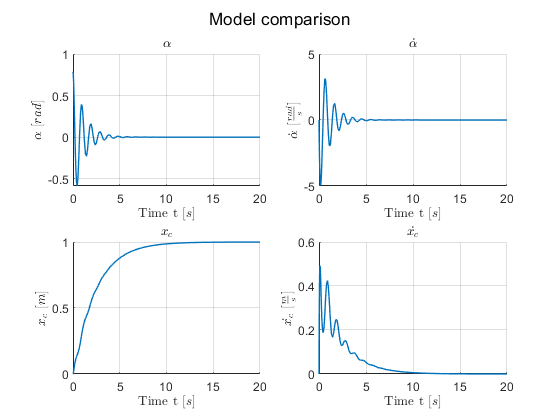


f1 = figure;
sgtitle("Model comparison")
subplot(221);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(1,:), "LineWidth", 1)
%plot(solutionLinear.t, solutionLinear.x(:,1), "LineWidth", 1, "LineStyle","--")
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\alpha$ [$rad$]', 'Interpreter', 'Latex')
  title('$\alpha$', 'Interpreter', 'Latex')
  
  subplot(222);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(2,:), "LineWidth", 1)
%plot(solutionLinear.t, solutionLinear.x(:,2), "LineWidth", 1, "LineStyle","--")
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{\alpha}$ [$\frac{rad}{s}$]', 'Interpreter', 'Latex')
  title('$\dot{\alpha}$', 'Interpreter', 'Latex')
  
  subplot(223);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(3,:), "LineWidth", 1)
%plot(solutionLinear.t, solutionLinear.x(:,3), "LineWidth", 1, "LineStyle","--")
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$x_c$ [$m$]', 'Interpreter', 'Latex')
  title('$x_c$', 'Interpreter', 'Latex')
  
  subplot(224);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(4,:), "LineWidth", 1)
%plot(solutionLinear.t, solutionLinear.x(:,4), "LineWidth", 1, "LineStyle","--")
%legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{x_c}$ [$\frac{m}{s}$]', 'Interpreter', 'Latex')
  title('$\dot{x_c}$', 'Interpreter', 'Latex')